# Bifurcaciones en sistemas unidimensionales

clc;clear;close all

## Bifurcación Saddle-Node

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =\mathrm{rx}-\frac{x}{1+x^2 }$$


Donde $r$ es el parámetro de bifurcación

syms x r
Fsn = r*x-(x/(1+x^2))

$$Fsn = r\,x-\frac{x}{x^{2}+1}$$

r_asignado=0.5; %Asigno valor.
disp("Ejercicio 3.4.1");

Ejercicio 3.4.1


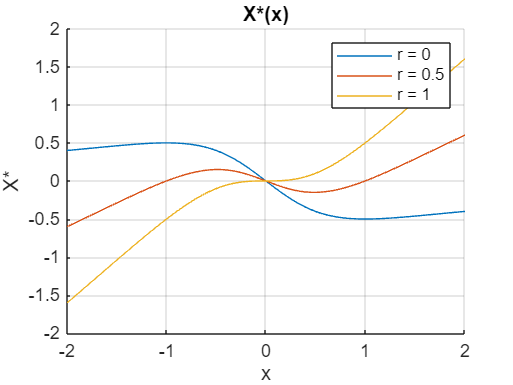


% GRAFICA X*(x):
r_desde = 0;
r_hasta = 1;
r_paso = 0.5; % Reducido el paso para una mejor visualización
r_grafica = r_desde:r_paso:r_hasta; % Vector de valores de r
x_desde = -3;
x_hasta = 3;
x_grafica = linspace(x_desde, x_hasta, 100);

figure; % Abre una nueva figura para la gráfica
hold on;

for i = 1:length(r_grafica)
    Fsn_grafica = real(subs(subs(Fsn, r, r_grafica(i)), x, x_grafica)); % Sustituye r y x por valores específicos y evalúa Fsn
    plot(x_grafica, Fsn_grafica); % Grafica Fsn con valores de r específicos
end
xlim([-2 2])
ylim([-2 2]) 
grid on
title("X*(x)");
xlabel("x")
ylabel("X*")
hold off;
legend(arrayfun(@(r) ['r = ' num2str(r)], r_grafica', 'UniformOutput', false)); % Crea la leyenda con los valores de r

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100)

$$xss\_sn = \left(\begin{array}{c} 0\\ \frac{\sqrt{-r\,\left(r-1\right)}}{r}\\ -\frac{\sqrt{-r\,\left(r-1\right)}}{r} \end{array}\right)$$

En este caso, tenemos 3 PE. Por lo que se linealiza en estos puntos

A = jacobian(Fsn,x);

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1

$$A\_a = r-1$$

A_aposible=double(subs(A_a,r,r_asignado))

A_aposible = -0.5000

A_b = subs(A,x,xss_sn(2)) % Para el punto de equilibrio 2 

$$A\_b = r+\frac{1}{\frac{r-1}{r}-1}-\frac{2\,\left(r-1\right)}{r\,{\left(\frac{r-1}{r}-1\right)}^{2}}$$

A_bposible=double(subs(A_b,r,r_asignado))

A_bposible = 0.5000

A_c = subs(A,x,xss_sn(3))

$$A\_c = r+\frac{1}{\frac{r-1}{r}-1}-\frac{2\,\left(r-1\right)}{r\,{\left(\frac{r-1}{r}-1\right)}^{2}}$$

A_cposible=double(subs(A_c,r,r_asignado))

A_cposible = 0.5000

En este caso, para los tres PE se hace el siguiente análisis:

- Para $x_a =0$

Se tiene que el jacobiano $A=r-1$, para este caso $r<1$, con el fin de tener un valor estable para este polo. 

- Para $x_b =\frac{\sqrt{-r\,\left(r-1\right)}}{r}=\sqrt{\frac{1}{r}-1}$

Se tiene que el jacobiano $A=$$r+\frac{1}{\frac{r-1}{r}-1}-\frac{2\,\left(r-1\right)}{r\,{\left(\frac{r-1}{r}-1\right)}^2 }$ que se reduce a $$2r-2r^2$  para este caso, se debe cumplir que $0<r\le 1$, para que los valores de $x_b$ sean reales, aunque esto haga que el polo sea inestable.

- Para $x_c =-\frac{\sqrt{-r\,\left(r-1\right)}}{r}=-\sqrt{\frac{1}{r}-1}$

Se tiene que el jacobiano $$A=2r-2r^2$, nuevamente, se debe cumplir que $0<r\le 1$, para que los valores de $x_b$ sean reales aunque esto haga que el polo sea inestable.

Si hacemos que $r=0\ldotp 2$ 

xss_sn_num = double(subs(xss_sn,r,r_asignado))

xss_sn_num =      0
     1
    -1


## Simulación de la Bifurcación Saddle - Node

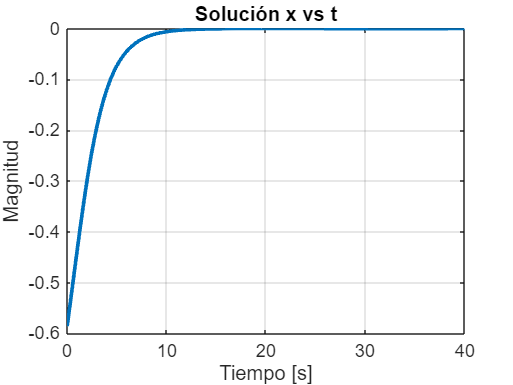

Tsim = 40;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = -0.6;        % Condiciones iniciales
Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(0.01,2 ,Ns);
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode(t,x,r_asignado), [0 Ts], x0);
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

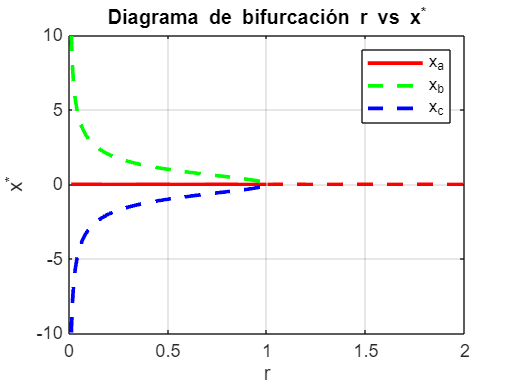


plot(r_sim(r_sim < 1), real(fr(1, r_sim <1)), 'LineWidth', 2, 'Color', 'r'); 
hold on
plot(r_sim(r_sim >0 & r_sim<1), real(fr(2,r_sim >0 & r_sim<1)), 'LineWidth', 2, 'Color', 'g',"LineStyle","--");
plot(r_sim(r_sim >0 & r_sim<1), real(fr(3,r_sim >0 & r_sim<1)), 'LineWidth', 2, 'Color', 'b',"LineStyle","--"); 
plot(r_sim(r_sim > 1), real(fr(1, r_sim >1)), 'LineWidth', 2, 'Color', 'r', "LineStyle","--"); 
hold off
legend(["x_a" "x_b" "x_c"])
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
grid on

Los valores que aparecen entre -2 y +2 no deben ser tenidos en cuenta, ya que estos valores cuentan con parte imaginaria y por ahora, eso no tiene sentido

#### Bifurcación Saddle - Node

function dxdt = saddlenode(t,x,r)
    dxdt = r*x-(x/(1+x^2));
end